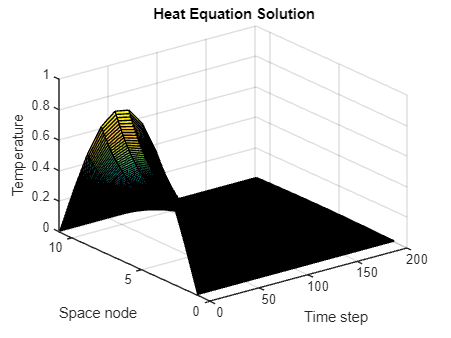

L = 1;
T = 0.5;
C = 1;
N = 10;
M = 200;
h = L/N;
k = T/M;
lambda = k/(C*h^2);
x = 0:h:L;
u = zeros(N+1,M+1);
% Initial condition
for i=1:N+1
u(i,1) = sin(pi*x(i));
end
% Boundary conditions
u(1,:) = 0;
u(N+1,:) = 0;
% Finite difference iteration
for j=1:M
for i=2:N
u(i,j+1) = (1-2*lambda)*u(i,j) + ...
lambda*(u(i-1,j) + u(i+1,j));
end
end
surf(u)
xlabel('Time step')
ylabel('Space node')
zlabel('Temperature')
title('Heat Equation Solution')

L = 1;
T = 0.5;
C = 1;

h = 0.25;
k = 0.02;

N = L/h;      % 4
M = T/k;

lambda = k/(C*h^2);

x = 0:h:L;
u = zeros(N+1, M+1);

% Initial condition: u(x,0) = x(1-x)
for i = 1:N+1
    u(i,1) = x(i)*(1 - x(i));
end

% Boundary conditions
u(1,:) = 0;
u(N+1,:) = 0;

% Finite difference iteration
for j = 1:M
    for i = 2:N
        u(i,j+1) = (1 - 2*lambda)*u(i,j) + ...
                   lambda*(u(i-1,j) + u(i+1,j));
    end
end

% -------------------------------
% DISPLAY GRID TABLE (IMPORTANT)
% -------------------------------

disp('Grid Point Table:')

Grid Point Table:


disp('---------------------------------------------')

---------------------------------------------


disp(' i      x(i)        u(i,0)        u(i,1)')

 i      x(i)        u(i,0)        u(i,1)



for i = 1:N+1
    fprintf('%d    %0.2f      %0.4f      %0.4f\n', ...
        i-1, x(i), u(i,1), u(i,2));
end

0    0.00      0.0000      0.0000
1    0.25      0.1875      0.1475
2    0.50      0.2500      0.2100
3    0.75      0.1875      0.1475
4    1.00      0.0000      0.0000


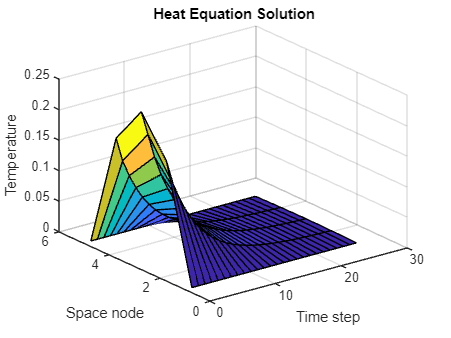


% -------------------------------
% SURFACE PLOT
% -------------------------------
surf(u)
xlabel('Time step')
ylabel('Space node')
zlabel('Temperature')
title('Heat Equation Solution')

L = 1;
T = 0.02;
C = 1;

h = 0.25;
k = 0.01;

N = L/h;      % 4
M = T/k;

lambda = k/(C*h^2);

x = 0:h:L;
t = 0:k:T;
u = zeros(N+1, M+1);

% Initial condition: sin(pi*x)
for i = 1:N+1
     u(i,1) = sin(pi*x(i));
end

% Boundary conditions
u(1,:) = 0;
u(N+1,:) = 0;

% Finite difference iteration
for j = 1:M
    for i = 2:N
        u(i,j+1) = (1 - 2*lambda)*u(i,j) + ...
                   lambda*(u(i-1,j) + u(i+1,j));
    end
end

% -------------------------------
% DISPLAY GRID TABLE (IMPORTANT)
% -------------------------------

disp('Grid Point Table:')

Grid Point Table:


disp('---------------------------------------------')

---------------------------------------------


disp(' i      x(i)        u(i,0)        u(i,1)')

 i      x(i)        u(i,0)        u(i,1)



for i = 1:N+1
    fprintf('%d    %0.2f      %0.4f      %0.4f\n', ...
        i-1, x(i), u(i,1), u(i,2));
end

0    0.00      0.0000      0.0000
1    0.25      0.7071      0.6408
2    0.50      1.0000      0.9063
3    0.75      0.7071      0.6408
4    1.00      0.0000      0.0000


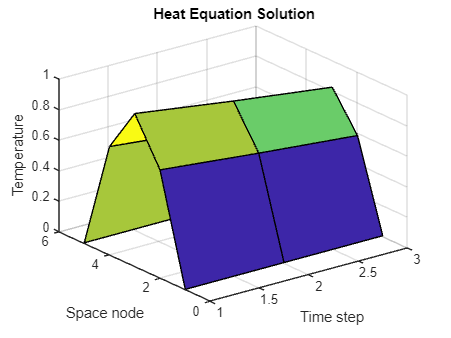


% -------------------------------
% SURFACE PLOT
% -------------------------------
surf(u)
xlabel('Time step')
ylabel('Space node')
zlabel('Temperature')
title('Heat Equation Solution')


% -------------------------------
% EXACT SOLUTION
% u(x,t) = e^(-pi^2 t) * sin(pi x)
% -------------------------------
u_exact = zeros(N+1, M+1);

for j = 1:M+1
    for i = 1:N+1
        u_exact(i,j) = exp(-pi^2 * t(j)) * sin(pi*x(i));
    end
end

% -------------------------------
% EXACT vs NUMERICAL COMPARISON
% -------------------------------
disp(' ')

disp('Comparison Table')

Comparison Table


disp('--------------------------------------------------------------------------')

--------------------------------------------------------------------------


disp(' i   x(i)   Num(t1)   Exact(t1)   Num(t2)   Exact(t2)')

 i   x(i)   Num(t1)   Exact(t1)   Num(t2)   Exact(t2)



for i = 1:N+1
    fprintf('%d  %0.2f   %0.4f    %0.4f     %0.4f    %0.4f\n', ...
        i-1, x(i), ...
        u(i,2), u_exact(i,2), ...
        u(i,3), u_exact(i,3));
end

0  0.00   0.0000    0.0000     0.0000    0.0000
1  0.25   0.6408    0.6407     0.5808    0.5804
2  0.50   0.9063    0.9060     0.8213    0.8209
3  0.75   0.6408    0.6407     0.5808    0.5804
4  1.00   0.0000    0.0000     0.0000    0.0000
